# Taller H infinito recuperación

Andrés ^3

clear
close all
load("HinfControllers.mat")
load("modelo_lin.mat")

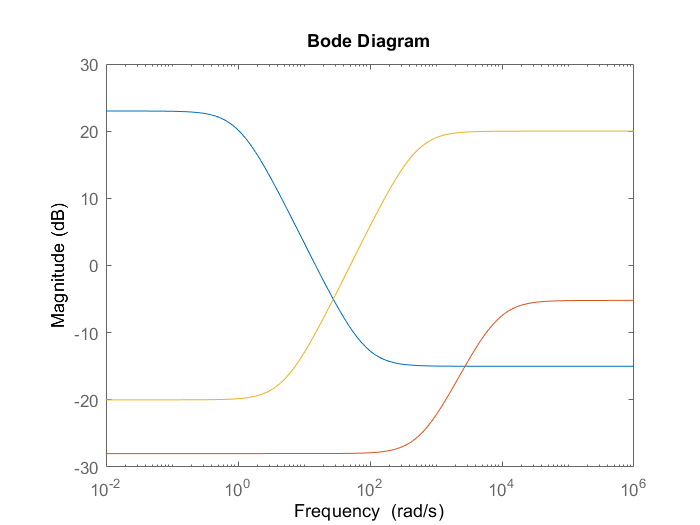

load("UncertainLinmodel.mat")
load("modelo_lin.mat")
latmod;
latmod.A(4,4) = 0;
latmod.A(5,4) = 0;

W1 = makeweight(db2mag(23),[15 db2mag(0)],db2mag(-15)); %filtro pasa bajos
W2 = makeweight(db2mag(-28),[600 db2mag(-25)],db2mag(-5.2)); 
W3 = makeweight(db2mag(-20),[50 db2mag(0)],db2mag(20)); %filtro pasa altos

figure(1)
bodemag(W1,W2,W3)

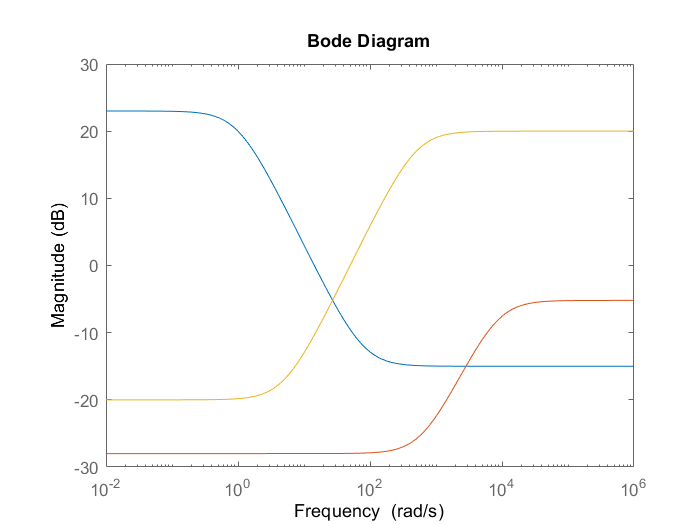



W1 = makeweight(db2mag(23),[1 db2mag(20)],db2mag(-15)); %filtro pasa bajos
W2 = makeweight(db2mag(-28),[8500 db2mag(-8.2)],db2mag(-5.2)); 
W3 = makeweight(db2mag(-20),[500 db2mag(17)],db2mag(20)); %filtro pasa altos

figure(1)
bodemag(W1,W2,W3)

%Peso de las perturbaciones
Wp      = makeweight(1,[10 0.1],0.01);
%Peso Error Ángulo Roll
W1Phi      = W1;
%Peso Error Ángulo Yaw
W1Psi      = W1;%makeweight(db2mag(23),[15 db2mag(0)],db2mag(-15));
%Peso Señal de Control Aileron
W2Aileron      = W2;
%Peso Señal de Control Rudder
W2Rudder      = W2;%makeweight(db2mag(-28),[600 db2mag(-25)],db2mag(-5.2));
%Peso Salida Ángulo Roll
W3Phi      = W3;
%Peso Salida Ángulo Yaw
W3Psi      = W3;%makeweight(db2mag(-10),[50 db2mag(0)],db2mag(25));
%Peso del ruido
Wn      = 0.001;
%Función Delta
%delta = ss([3 0; 0 1.5]);

systemnames     = 'latmod Wp Wn W1Phi W1Psi W2Aileron W2Rudder W3Phi W3Psi';
inputvar        = '[per; n; rPhi; rPsi; uAileron; uRudder]';
outputvar       = '[W1Phi; W1Psi; W2Aileron; W2Rudder; W3Phi; W3Psi; -latmod(4) - Wn + rPhi;-latmod(5) - Wn + rPsi]';
input_to_latmod   = '[-Wp + uAileron; -Wp + uRudder]';
input_to_Wn     = '[n]';
input_to_Wp     = '[per]';
input_to_W1Phi     = '[-latmod(4) - Wn + rPhi]';
input_to_W1Psi     = '[-latmod(5) - Wn + rPsi]';
input_to_W2Phi     = '[uAileron]';
input_to_W2Psi     = '[uRudder]';
input_to_W3Phi     = '[latmod(4)]';
input_to_W3Psi     = '[latmod(5)]';
%input_to_delta     = '[latmod(4); latmod(5)]';

%Planta generalizada
Planta = sysic;

%Diseño controlador Hinf
ncont = 2; 
nmeas = 2; 
[K_LatDir,CL,gamma] = hinfsyn(Planta,nmeas,ncont);

%Función de Lazo abierto
L = latmod*K_LatDir;

%Sistema en Lazo cerrado
Go = feedback(L,eye(2),[1,2],[4,5]);
Go.InputName={'aileron','rudder'}

Go =
 
  A = 
                 v           p
   v        -0.875      0.8751
   p        -2.831      -16.14
   r         1.706      0.5154
   phi           0           1
   psi           0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
 
                 r         phi
   v        -16.82       9.791
   p         3.377           0
   r        -2.783           0
   phi     0.05385           0
   psi       1.001           0
   ?             0      -78.08
   ?             0       36.76
   ?             0       16.74
   ?             0       13.91
   ?             0       7.431
   ?             0       1.988
   ?             0          -4
   ?             0  -1.

%Ancho de banda de los sistemas
BWPhi = bandwidth(Go(4,1))/2/pi

BWPhi = 5.7307

BWPsi = bandwidth(Go(5,2))/2/pi

BWPsi = 4.8510

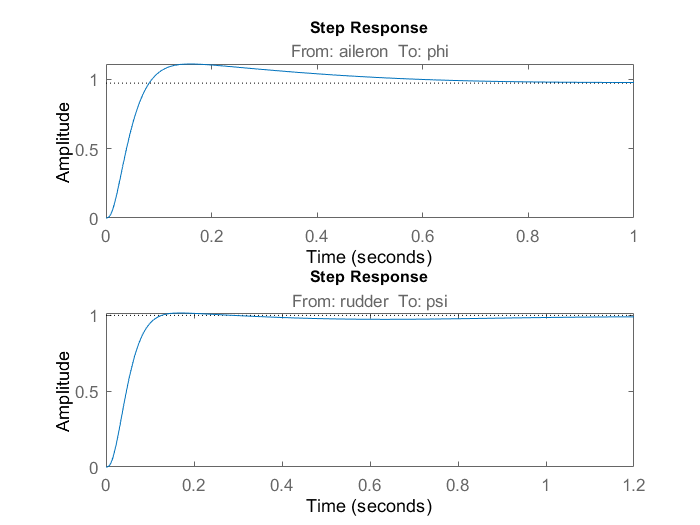

% Respuesta al paso del sistema
figure()
subplot(2,1,1)
step(Go(4,1));

subplot(2,1,2)
step(Go(5,2));

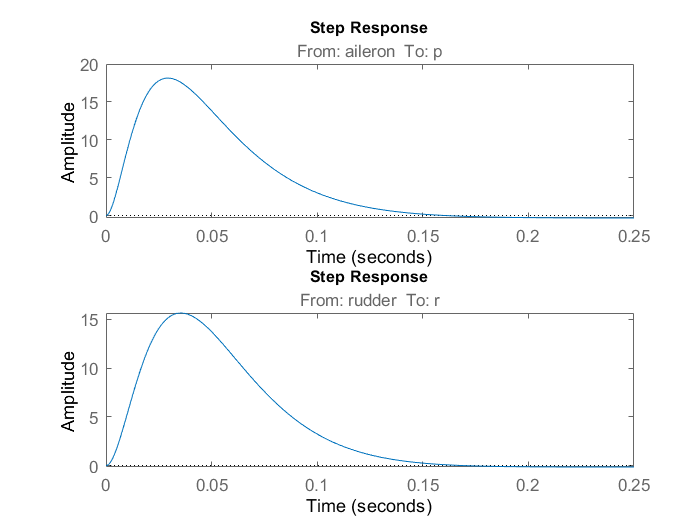


figure()
subplot(2,1,1)
step(Go(2,1));

subplot(2,1,2)
step(Go(3,2));

RespuestaEscalon = stepinfo(Go(4,1))

RespuestaEscalon = struct with fields:
        RiseTime: 0.0526
    SettlingTime: 0.6545
     SettlingMin: 0.8770
     SettlingMax: 1.1105
       Overshoot: 14.1461
      Undershoot: 0
            Peak: 1.1105
        PeakTime: 0.1600


RespuestaEscalon2 = stepinfo(Go(5,2))

RespuestaEscalon2 = struct with fields:
        RiseTime: 0.0689
    SettlingTime: 0.8463
     SettlingMin: 0.9005
     SettlingMax: 1.0159
       Overshoot: 1.5873
      Undershoot: 0
            Peak: 1.0159
        PeakTime: 0.1684



RespuestaEscalonP_v = stepinfo(Go(2,1))

RespuestaEscalonP_v = struct with fields:
        RiseTime: 0
    SettlingTime: 0.1424
     SettlingMin: -0.3296
     SettlingMax: 18.1388
       Overshoot: Inf
      Undershoot: Inf
            Peak: 18.1388
        PeakTime: 0.0290


RespuestaEscalonR_v = stepinfo(Go(3,2))

RespuestaEscalonR_v = struct with fields:
        RiseTime: 0
    SettlingTime: 0.1469
     SettlingMin: -0.1501
     SettlingMax: 15.6655
       Overshoot: Inf
      Undershoot: Inf
            Peak: 15.6655
        PeakTime: 0.0354
